# **기계제어공학부 기전융합종합설계 **

#### **Patient-Friendly Falling Suspicion Alarm System Based on 3D Bounding Box on 3D LiDAR Point Cloud**

Name:        Hong Se Hyun

Date:          2022.12.02.

# **Set-Up**

clc;     clear all;     close all;

addpath(genpath('config'))
addpath(genpath('eval'))
addpath(genpath('models'))
addpath(genpath('utils'))

warning ('off','all');

**Load Dataset**

[matFiles, numFiles, mydata] = DataProcess_LoadData('testdata_demo');

mydata_path = "../data/testdata_demo/labeling_NTH214_1025_2000_PARKJUEUN.mat"

**Load Pre-Trained Model**

% Decision_Tree = load('config/20221201_label_2/trained_Tree_Mdl.mat');
Decision_Tree = load('config/trained_Tree_Mdl_non_normalization.mat');

**Data Setting**

human_name      = cell(numFiles, 1);
matFiles_name   = split(matFiles(1).name, '.');
human_name_cell = split(matFiles_name(1), '_');
human_name(1)   = human_name_cell(size(human_name_cell, 1));

% PARK JU EUN
test_frame_info(1).name           = human_name(1);
test_frame_info(1).human_detected = [240,  255,  300,  350,  390,  525,  780,  860,  900,  970,  1050, 1100];
test_frame_info(1).lying_detected = [2400, 2510, 2550, 2640, 3060, 3260, 4120, 4180, 4740, 4880];

LABEL_human_detected = {};
LABEL_lying_detected = {};

for itr = 1 : numFiles
    [TMP_LABEL_human_detected, TMP_LABEL_lying_detected] = DataProcess_GetLabel_2(mydata{itr,1}, test_frame_info(itr).human_detected, test_frame_info(itr).lying_detected);
    
    LABEL_human_detected = [LABEL_human_detected ; TMP_LABEL_human_detected];
    LABEL_lying_detected = [LABEL_lying_detected ; TMP_LABEL_lying_detected];
end

Dataset = [LABEL_human_detected ; LABEL_lying_detected]

Dataset = 1000×1 cell 배열
    {[1.1306 2.4882 -0.1033 0.5606 0.7285 1.5617 0 0 0]}
    {[1.1280 2.5057 -0.0934 0.5657 0.7038 1.5814 0 0 0]}
    {[1.1255 2.5232 -0.0835 0.5708 0.6791 1.6012 0 0 0]}
    {[1.1229 2.5407 -0.0737 0.5760 0.6544 1.6209 0 0 0]}
    {[1.1060 2.5675 -0.0720 0.5769 0.6465 1.6241 0 0 0]}
    {[1.0890 2.5942 -0.0704 0.5779 0.6386 1.6273 0 0 0]}
    {[1.0720 2.6210 -0.0688 0.5788 0.6307 1.6306 0 0 0]}
    {[1.0587 2.6542 -0.0712 0.5781 0.6390 1.6258 0 0 0]}
    {[1.0454 2.6874 -0.0736 0.5775 0.6473 1.6210 0 0 0]}
    {[1.0321 2.7206 -0.0760 0.5768 0.6556 1.6162 0 0 0]}
    {[1.0073 2.7297 -0.0327 0.5696 0.6494 1.5665 0 0 0]}
    {[ 0.9825 2.7389 0.0107 0.5624 0.6432 1.5168 0 0 0]}
    {[ 0.9577 2.7481 0.0540 0.5552 0.6370 1.4671 0 0 0]}
    {[ 0.9253 2.8110 0.0199 0.5211 0.7026 1.5353 0 0 0]}
    {[0.8929 2.8739 -0.0142 0.4869 0.7681 1.6035 0 0 0]}
    {[0.0634 2.2170 -0.0564 0.4648 0.5991 1.2382 0 0 0]}


% Define BED Coordinates
min_bed_x = -1.5;
max_bed_x = -0.5;

min_bed_y = 2;
max_bed_y = 4;

# **Detecting DEMO**

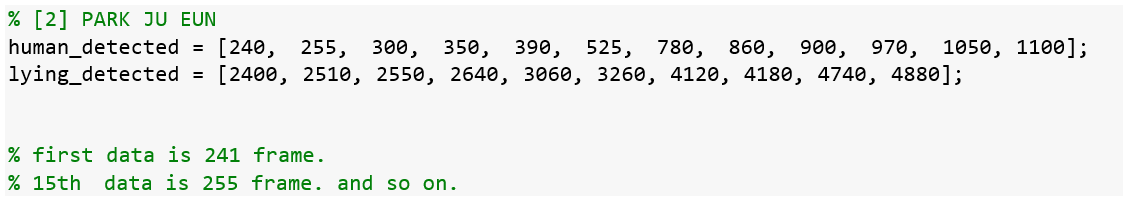

search = 888;

tic

TestData = Dataset(search, :);

detected_bbox_coordinates = DataProcess_BboxesExtraction(1, TestData);        % Get Bbox Coordinates
detected_features = DataProcess_FeatureExtraction(detected_bbox_coordinates); % Feature Extraction

TestData_predict = predict(Decision_Tree.Tree_Mdl, detected_features);

if string(TestData_predict(1)) == 'lying_detected'
    coordinate_x = TestData{1}(1);
    coordinate_y = TestData{1}(2);
    if not (coordinate_x > min_bed_x & coordinate_x < max_bed_x) & (coordinate_y > min_bed_y & coordinate_y < max_bed_y)
        TestData_predict(1) = {'ABNORMAL_Lying_detected'};
    end
end

toc

경과 시간은 0.010480초입니다.


TestData_predict

TestData_predict = 1×1 cell 배열
    {'ABNORMAL_Lying_detected'}


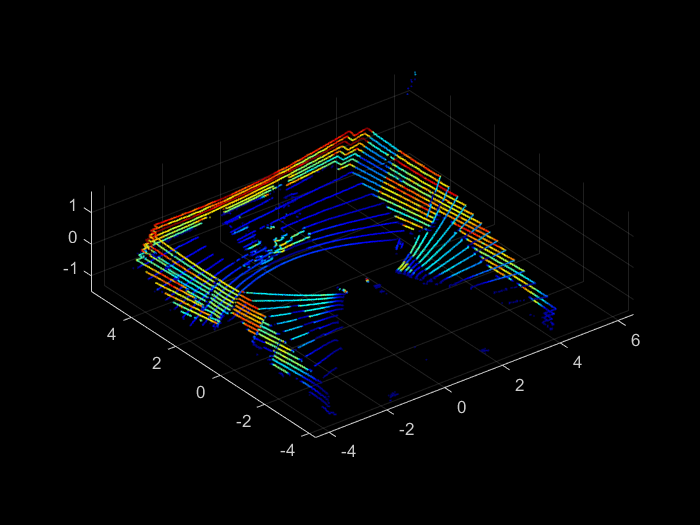

veloReader        = velodyneFileReader('../data/pcap/20221025_2000_PARKJUEUN.pcap','VLP16');
visualization_idx = Filter_FrameSet(search);
ptc               = readFrame(veloReader, visualization_idx);
pcshow(ptc)